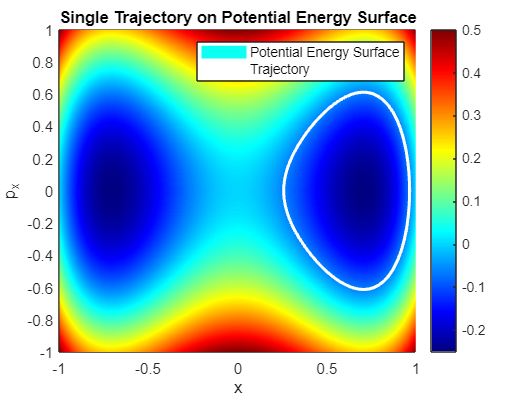

clear
format long

% Set system parameters
alpha = 1;
delta = 0;
beta = 0;

% Hamiltonian system
hamiltonian_system = @(t, u) [
    u(3); % x' = px
    u(4); % y' = py
    -4*u(1)^3 + 2*alpha*u(1) + delta - 2*beta*u(1)*u(2)^2;  % px' equation
    -4*u(2)^3 + 2*u(2) - 2*beta*u(1)^2*u(2) % py' equation
];

% Parameters for time and step size
t_min = -10;
t_max = 10;
h = 0.05;
N = (t_max - t_min) / h;
t = linspace(t_min, t_max, N+1);

% Initial condition (x0, y0, px0, py0)
x0 = 0.5; 
y0 = 0; 
px0 = 0.5;
py0 = 0;
U0 = [x0; y0; px0; py0];

% Integrate trajectory
U = zeros(4, N+1);
U(:, 1) = U0;

for n = 1:N
    % Runge-Kutta 4th order method
    k1 = hamiltonian_system(t(n), U(:, n));
    k2 = hamiltonian_system(t(n) + 0.5*h, U(:, n) + 0.5*h*k1);
    k3 = hamiltonian_system(t(n) + 0.5*h, U(:, n) + 0.5*h*k2);
    k4 = hamiltonian_system(t(n) + h, U(:, n) + h*k3);
    U(:, n+1) = U(:, n) + h * (1/6 * k1 + 1/3 * k2 + 1/3 * k3 + 1/6 * k4);
end

% Compute potential energy surface only for visualization
[x_grid, px_grid] = meshgrid(linspace(-1, 1, 100), linspace(-1, 1, 100));
V = x_grid.^4 - alpha*x_grid.^2 + delta*x_grid + 0.5 * px_grid.^2;

% Plot potential energy surface
figure;
pcolor(x_grid, px_grid, V);
shading interp;
colormap(jet);
colorbar;
hold on;

% Plot single trajectory (x, px) on top of potential energy surface
plot(U(1, :), U(3, :), 'w', 'LineWidth', 2);
xlabel('x');
ylabel('p_x');
title('Single Trajectory on Potential Energy Surface');
legend('Potential Energy Surface', 'Trajectory');